**Initial Setup**

clear all
close all
clc

lagrange  = '../final_tests/Coupling Darcy-Richards/lagrange_hard_coupling/csv/';
reference = '../tests/richards_initial_tests/benchamark_problem/single_stage_primal/csv/';

lagrange_files = struct2table(dir(append(lagrange, '*.csv')));
lagrange_files = sortrows(lagrange_files, 3);

reference_files = struct2table(dir(append(reference, '*.csv')));
reference_files = sortrows(reference_files, 3);

**Import files**

lagrange_shape = size(lagrange_files);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "h", "p"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
for j = 1:lagrange_shape(1)
    name = lagrange_files.name{j};
    lagrange_data(j, :, :) = table2array(readtable(append(lagrange, name), opts));
end

reference_shape = size(reference_files);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "h"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
for j = 1:reference_shape(1)
    name = reference_files.name{j};
    reference_data(j, :, :) = table2array(readtable(append(reference, name), opts));
end

sol_diff = zeros(15, 9801);

for j = 1:15
    sol_diff(j, :) = reference_data(j, :, 3) - lagrange_data(j, :, 3);
    no(j) = norm(sol_diff(j, :)) / norm(reference_data(j, :, 3));
end

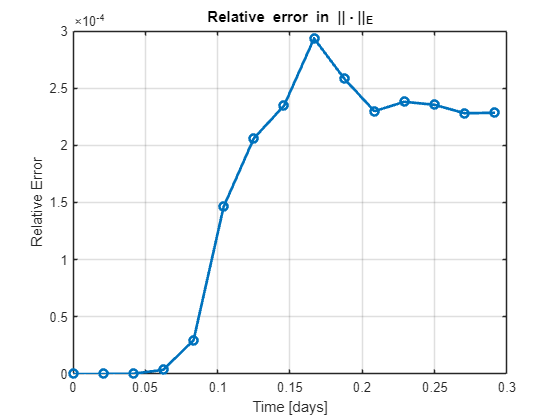

figure 
plot(linspace(0, 0.29167, 15), no, '-o','LineWidth',2)
grid
title('Relative error in ||\cdot||_E')
xlabel('Time [days]')
ylabel('Relative Error')